# Àlgebra lineal - Resolució de sistemes

A = [1 2 1; -2 7 3; 1 -1 10]

A =      1     2     1
    -2     7     3
     1    -1    10


det(A)

ans =    114


norm(A,1)               % per columnes

ans =     14


norm(A, 'inf')          % per files

ans =     12


norm(A,2)               % sqrt(eig(A*A'))

ans =        10.626


max(sqrt(eig(A*A')))    % Norma 2

ans =        10.626


B = inv(A); B*A, A*B

ans =             1  -3.4694e-17    1.249e-16
  -6.9389e-18            1            0
            0            0            1


ans =             1   3.1225e-17   1.3878e-17
   1.6653e-16            1            0
  -5.5511e-17   5.5511e-17            1


[V,D] = eig(A)          % Valors propis

V =       0.91903     -0.34633      0.24387
      0.38888     -0.92036      0.67345
    -0.064465     -0.18162      0.69785


D =        1.7761            0            0
            0       6.8394            0
            0            0       9.3844


inv(V)*A*V              % Matriu diagonal

ans =        1.7761  -5.4809e-15   5.2458e-15
  -1.4433e-15       6.8394   7.9936e-15
            0  -1.3323e-15       9.3844


#### Diverses matrius

zeros(5), ones(5), eye(5)

ans =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


ans =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


rand(5), randi(2,4)

ans =        0.9104      0.12232      0.71728      0.41954      0.59262
      0.18143      0.59265      0.86076      0.58577      0.21336
      0.69906      0.79716      0.86013      0.38191      0.41165
      0.53122      0.17526      0.95451      0.39563      0.90666
      0.38284      0.44309      0.42841      0.50956      0.85248


ans =      1     2     1     1
     2     1     2     1
     1     1     2     2
     2     2     1     2


hilb(4), invhilb(4)

ans =             1          0.5      0.33333         0.25
          0.5      0.33333         0.25          0.2
      0.33333         0.25          0.2      0.16667
         0.25          0.2      0.16667      0.14286


ans =           16        -120         240        -140
        -120        1200       -2700        1680
         240       -2700        6480       -4200
        -140        1680       -4200        2800


M = magic(5)

M =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


D = diag(diag(M))

D =     17     0     0     0     0
     0     5     0     0     0
     0     0    13     0     0
     0     0     0    21     0
     0     0     0     0     9


v = [1 2 3 4 6];
diag(v)

ans =      1     0     0     0     0
     0     2     0     0     0
     0     0     3     0     0
     0     0     0     4     0
     0     0     0     0     6


tril(M), tril(M,-1)

ans =     17     0     0     0     0
    23     5     0     0     0
     4     6    13     0     0
    10    12    19    21     0
    11    18    25     2     9


ans =      0     0     0     0     0
    23     0     0     0     0
     4     6     0     0     0
    10    12    19     0     0
    11    18    25     2     0


triu(M), triu(M,-1), triu(M,1)

ans =     17    24     1     8    15
     0     5     7    14    16
     0     0    13    20    22
     0     0     0    21     3
     0     0     0     0     9


ans =     17    24     1     8    15
    23     5     7    14    16
     0     6    13    20    22
     0     0    19    21     3
     0     0     0     2     9


ans =      0    24     1     8    15
     0     0     7    14    16
     0     0     0    20    22
     0     0     0     0     3
     0     0     0     0     0


#### Exercici

A = -eye(20);
b = 1:20;
i = 1;
while (i <= 20)
    b(i) = 2^(-i);
    j = 1;
    while (j <= 20)
        if (i < j)
            A(i,j) = j;
        elseif (i == j)
            A(i,j) = -1;
        else
            A(i,j) = 0;
        end
        j = j + 1;
    end
    i = i + 1;
end
[A, b']

ans =            -1            2            3            4            5            6            7            8            9           10           11           12           13           14           15           16           17           18           19           20          0.5
            0           -1            3            4            5            6            7            8            9           10           11           12           13           14           15           16           17           18           19           20         0.25
            0            0           -1            4            5            6            7            8            9           10           11           12           13           14           15           16           17           18           19           20        0.125
            0            0            0           -1            5            6            7            8            9           10           11           12           13   

format short g
x = backsubs(A,b')

x =   -2.5652e+13
  -8.5506e+12
  -2.1377e+12
  -4.2753e+11
  -7.1255e+10
  -1.0179e+10
  -1.2724e+09
  -1.4138e+08
  -1.4138e+07
  -1.2853e+06


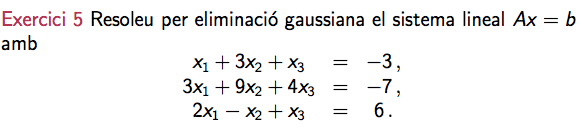

A = [ 1 3 1; 3 9 4; 2 -1 1];
b = [-3 -7 6]';
X = A\b                 % solució del sistema

X =             1
           -2
            2


%lugui(A)
[L,U,P] = lu(A)

L =             1            0            0
      0.66667            1            0
      0.33333            0            1


U =             3            9            4
            0           -7      -1.6667
            0            0     -0.33333


P =      0     1     0
     0     0     1
     1     0     0


y = L\(P*b), forward(L,P*b)

y =            -7
       10.667
     -0.66667


ans =            -7
       10.667
     -0.66667


x = U\y, backsubs(U,y)

x =             1
           -2
            2


ans =             1
           -2
            2


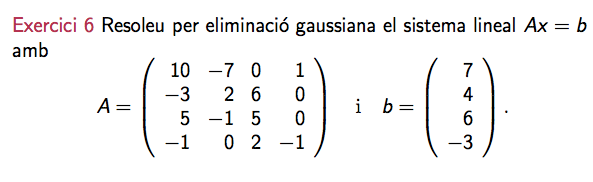

clear vars
A = [10 -7 0 1; -3 2 6 0; 5 -1 5 0; -1 0 2 -1];
b = [7;4;6;-3];
A\b

ans =       0.43243
      0.21622
      0.81081
       4.1892


cond(A)

ans =          13.6


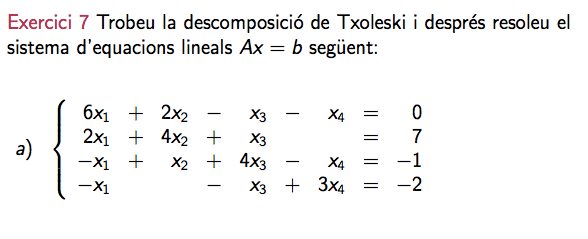

clear vars
A = [6 2 -1 -1; 2 4 1 0; -1 1 4 -1; -1 0 -1 3];
b = [0;7;-1;-2];
isequal(A,A')           % Matriu simètrica

ans = logical
   1


R = chol(A)

R =        2.4495       0.8165     -0.40825     -0.40825
            0       1.8257       0.7303      0.18257
            0            0       1.8166     -0.71563
            0            0            0       1.5126


R'*R

ans =             6            2           -1           -1
            2            4            1            0
           -1            1            4           -1
           -1            0           -1            3



% 1) R'y = b
y = R'\b

y =             0
       3.8341
      -2.0918
      -2.7747



% 2) Rx = y
x = R\y

x =       -1.6291
       3.0331
      -1.8742
      -1.8344



A\b

ans =       -1.6291
       3.0331
      -1.8742
      -1.8344


#### Factorització A = L*U

#### Factorització A simètrica A = R'*R

#### Factorització QR qr(A) = [Q,R]

Q = ortogonal

R = Triangular superior

QRx = b

Q(Rx) = b

Rx = Q'b

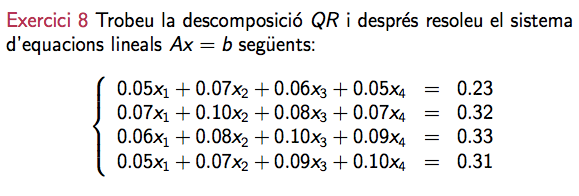

clear vars
A = [0.05 0.07 0.06 0.05; 0.07 0.1 0.08 0.07; 0.06 0.08 0.1 0.09; 0.05 0.07 0.09 0.1]

A =          0.05         0.07         0.06         0.05
         0.07          0.1         0.08         0.07
         0.06         0.08          0.1         0.09
         0.05         0.07         0.09          0.1


b = [0.23 0.32 0.33 0.31]'

b =          0.23
         0.32
         0.33
         0.31


[q,r] = qr(A)

q =      -0.43033    -0.084395     -0.36953     -0.81923
     -0.60246     -0.57389     -0.25706      0.49154
      -0.5164      0.81019     -0.12853      0.24577
     -0.43033    -0.084395      0.88366     -0.16385


r =      -0.11619      -0.1618     -0.16439      -0.1532
            0   -0.0043885     0.022449     0.020086
            0            0     0.023939     0.040327
            0            0            0  -0.00081923



% 1) rx = q'b
x = backsubs(r,(q'*b))

x =             1
            1
            1
            1


B = [1 -1 -1; 2 0 7; -1 1 1]

B =      1    -1    -1
     2     0     7
    -1     1     1


[q,r] = qr(B)

q =      -0.40825      0.57735      0.70711
      -0.8165     -0.57735   2.2204e-16
      0.40825     -0.57735      0.70711


r =       -2.4495       0.8165       -4.899
            0      -1.1547      -5.1962
            0            0   1.7764e-15


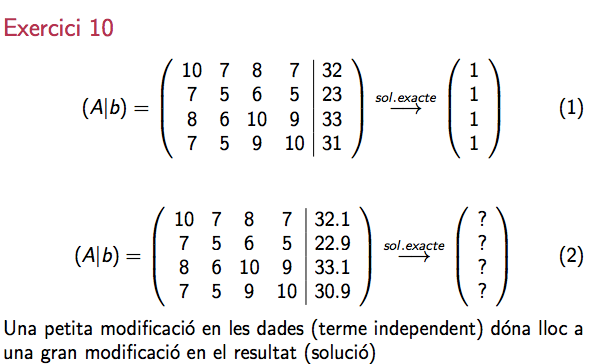

clear vars
A = [10 7 8 7; 7 5 6 5; 8 6 10 9; 7 5 9 10]

A =     10     7     8     7
     7     5     6     5
     8     6    10     9
     7     5     9    10


b = [32 23 33 31]'

b =     32
    23
    33
    31


b2 = [32.1 22.9 33.1 30.9]'

b2 =          32.1
         22.9
         33.1
         30.9


x = A\b, y = A\b2

x =             1
            1
            1
            1


y =           9.2
        -12.6
          4.5
         -1.1


r = norm(A*y-b,1)

r =           0.4


db = norm(b-b2,1)

db =           0.4


cond(A),det(A),rcond(A)

ans =        2984.1


ans =             1


ans =    0.00022282
